# Replicating Fig2 with events

And associated supplementals

## Decoding position demo

data_source = SessManager.load_special('Mouse2022');
opt = DecodeTensor.default_opt;
load(data_source.source_path);
traces = tracesEvents.events_transients;

[~, ~, trial_start, trial_end, trial_dir, ~, ks] =...
    DecodeTensor.new_sel(tracesEvents.position, opt);
within_trial = zeros(size(ks));
trial_start = trial_start(trial_dir==1);
trial_end = trial_end(trial_dir==1);
n_trials = numel(trial_start);
for i = 1:n_trials
    within_trial(trial_start(i):trial_end(i)) = i;
end

time_coord = (1:numel(ks))./opt.samp_freq;
if true
    first_half = (mod(within_trial,2) == 1) & (within_trial ~= 0);
    second_half = (mod(within_trial,2) == 0) & (within_trial ~= 0);
else
    first_half = (within_trial <= n_trials/2) & (within_trial ~= 0);
    second_half = (within_trial > n_trials/2) & (within_trial ~= 0);
end

ks_first_half = ks(first_half);
ks_second_half = ks(second_half);
X_first_half = traces(first_half, :);
X_second_half = traces(second_half, :);
X_first_half_s = shuffle(X_first_half, ks_first_half);
X_second_half_s = shuffle(X_second_half, ks_second_half);

alg = my_algs('ecoclin');
model1 = alg.train(X_first_half, ks_first_half); disp('m1');

m1


model1_s = alg.train(X_first_half_s, ks_first_half); disp('m1s');

m1s


model2 = alg.train(X_second_half, ks_second_half); disp('m2');

m2


model2_s = alg.train(X_second_half_s, ks_second_half); disp('m2s');

m2s



ps_first_half = alg.test(model2, X_first_half);
ps_first_half_s = alg.test(model2_s, X_first_half_s);
ps_first_half_d = alg.test(model2_s, X_first_half);
ps_second_half = alg.test(model1, X_second_half);
ps_second_half_s = alg.test(model1_s, X_second_half_s);
ps_second_half_d = alg.test(model1_s, X_second_half);

me_ = @(k,p) mean(abs(ceil(k(:)/2)-ceil(p(:)/2))).*opt.bin_width;
mse_ = @(k,p) mean((ceil(k(:)/2)-ceil(p(:)/2)).^2).*opt.bin_width.^2;
fprintf('Mean error: unsh: %f, sh: %f\n',  me_(ks_first_half, ps_first_half),...
    me_(ks_first_half, ps_first_half_s));

Mean error: unsh: 2.880467, sh: 0.919767


fprintf('Mean error: unsh: %f, sh: %f\n',  me_(ks_second_half, ps_second_half),...
    me_(ks_second_half, ps_second_half_s));

Mean error: unsh: 2.531590, sh: 1.056590




tr_track = within_trial(first_half|second_half);

ks_ = ks(within_trial~=0);
ps_(first_half) = ps_first_half;
ps_(second_half) = ps_second_half;
ps_ = ps_(within_trial~=0)';
ps_s_(first_half) = ps_first_half_s;
ps_s_(second_half) = ps_second_half_s;
ps_s_ = ps_s_(within_trial~=0)';

for i = 1:max(tr_track)
    tr_err(i) = me_(ks_(tr_track==i), ps_(tr_track==i));
    tr_err_s(i) = me_(ks_(tr_track==i), ps_s_(tr_track==i));
end

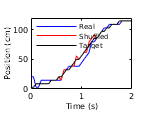

figure;
t = (1:numel(ks_first_half))./opt.samp_freq;
t_start = 83.5 + 2.05; %which to show
t_end = 83.5 + 4.05;%90;

hold on;
h(1) = plot(t - t_start, (ceil(ps_first_half/2) - 0.5)*opt.bin_width, '-b');
h(2) = plot(t - t_start, (ceil(ps_first_half_s/2) - 0.5)*opt.bin_width, '-r');
h(3) = plot(t - t_start, (ceil(ks_first_half/2) - 0.5)*opt.bin_width, '-k');

trial_boundaries = (find(diff(within_trial(first_half))>0)+0.5)./opt.samp_freq - t_start;
for i = 1:numel(trial_boundaries)
    x_ = trial_boundaries(i);
    line([x_ x_], ylim, 'Color', 'k', 'LineStyle', '--');
end
xlim([t_start t_end] - t_start);
ylim([-Inf Inf]);
xlabel 'Time (s)';
ylabel 'Position (cm)';
legend(h, 'Real', 'Shuffled', 'Target');
legend boxoff
legend location best
figure_format('boxsize', [1 0.7]*1.05); box on;
Utils.printto('events_figs/f2_events', 'decoding_demo.pdf');

## Confusion matrix

res = confusion_mat_runner(69);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 16).
Elapsed time is 301.309097 seconds.


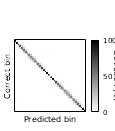

nt = res(1).num_trials;
C_pct = cat(3, res.C)/nt*100;
C_s_pct = cat(3, res.C_s)/nt*100;

figure;
PanelGenerator.plot_confusion(C_pct, 'Confusion (%)');
colormap gray
colormap(flipud(colormap(gca)));
Utils.printto('events_figs/f2_events', 'confusion_unshuffled.pdf');

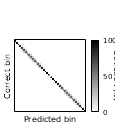


figure;
PanelGenerator.plot_confusion(C_s_pct, 'Confusion (%)');
colormap gray
colormap(flipud(colormap(gca)));
Utils.printto('events_figs/f2_events', 'confusion_shuffled.pdf');

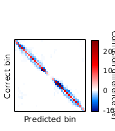


figure;
PanelGenerator.plot_confusion(C_s_pct - C_pct, 'Confusion difference (%)', false);
colormap(bluewhitered);
Utils.printto('events_figs/f2_events', 'confusion_diff.pdf');

## Decoding curves

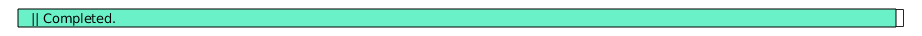

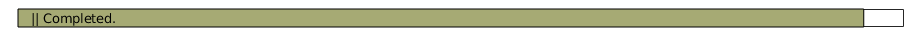

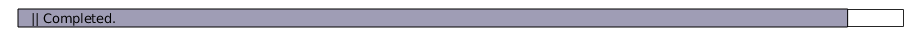

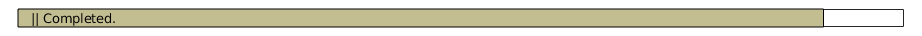

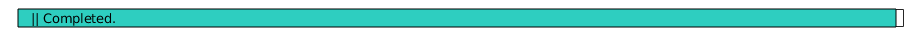

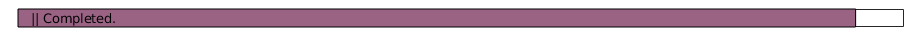

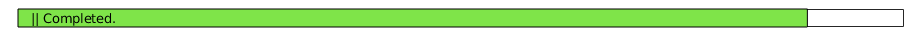

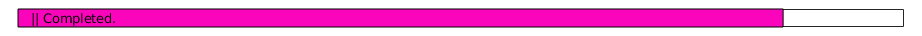

Unshuf R^2: -519.634606 - 0.999168, median: 0.996485
Shuf R^2: -1021.302369 - 0.998336, median: 0.983625
Diag R^2: -609.802187 - 0.999345, median: 0.994151
Unshuf (exp) R^2: -18.731794 - 0.999079, median: 0.996684
Shuf (exp) R^2: -32.908018 - 0.998339, median: 0.982250
Diag (exp) R^2: -20.255569 - 0.999299, median: 0.186787


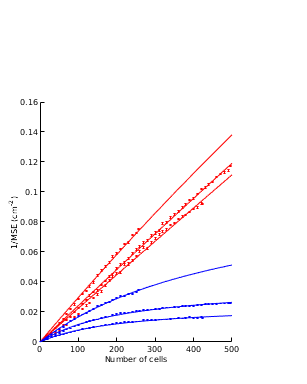

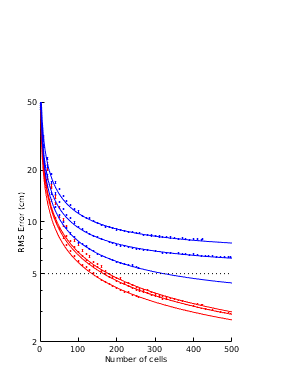

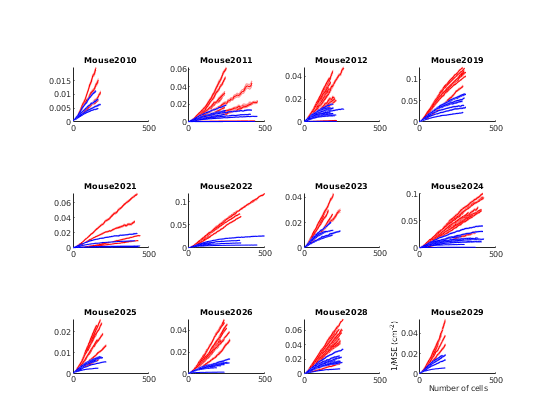

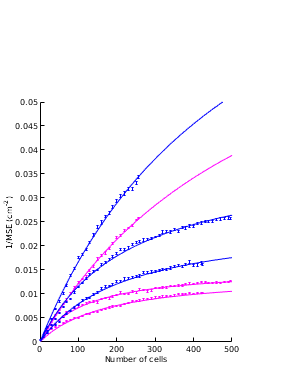

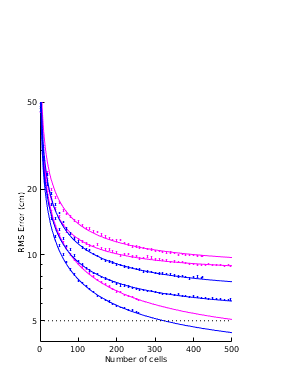

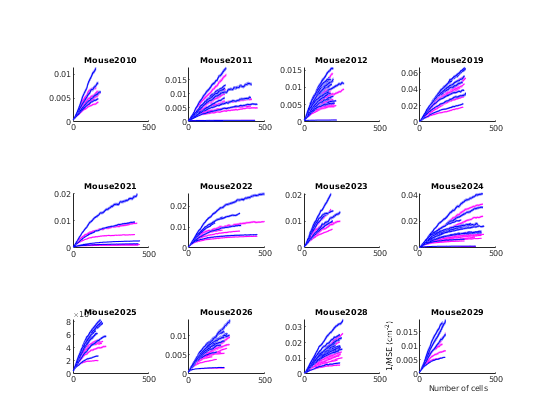

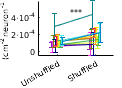

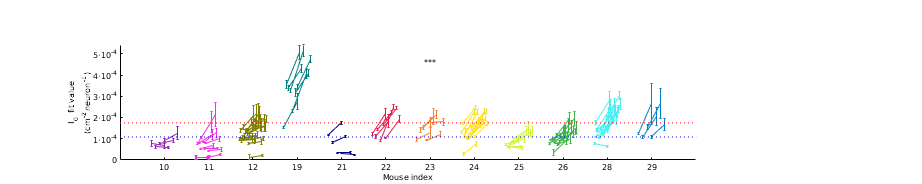

Value of I_0 across mice: 1.169628e-04 +- 4.474549e-05 (95% conf)
Value of I_0 (shuf) across mice: 1.758217e-04 +- 7.267200e-05 (95% conf)


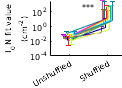

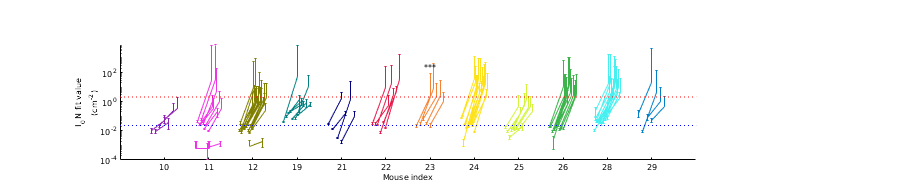

Value of I_0N across mice: 3.784266e-02 +- 3.607668e-02 (95% conf)
Value of I_0N (shuf) across mice: 5.854757e+00 +- 1.391202e+03 (95% conf)
Value of log(I_0N), postfunc: 8.758096e-03 - 5.527952e-02, mid: 2.200326e-02
Value of log(I_0N) (shuf), postfunc: 9.921950e-22 - 1.907787e+21, mid: 1.375826e+00


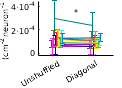

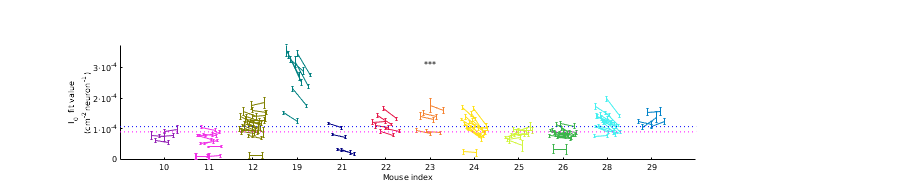

Value of I_0 across mice: 1.169628e-04 +- 4.474549e-05 (95% conf)
Value of I_0 (diag) across mice: 1.030251e-04 +- 3.632886e-05 (95% conf)


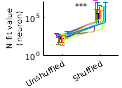

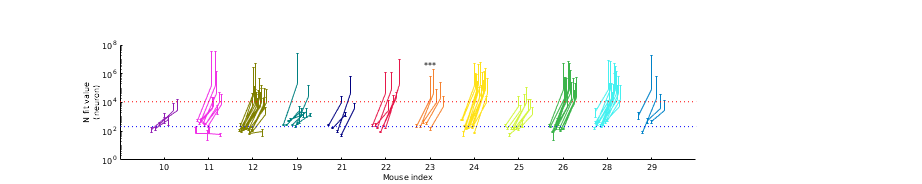

Value of N across mice: 2.900243e+02 +- 2.564928e+02 (95% conf)
Value of N (shuf) across mice: 2.925545e+04 +- 6.130231e+06 (95% conf)
Value of log(N), postfunc: 1.162031e+02 - 4.246154e+02, mid: 2.221298e+02
Value of log(N) (shuf), postfunc: 7.015418e-18 - 1.329603e+25, mid: 9.658012e+03


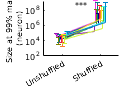

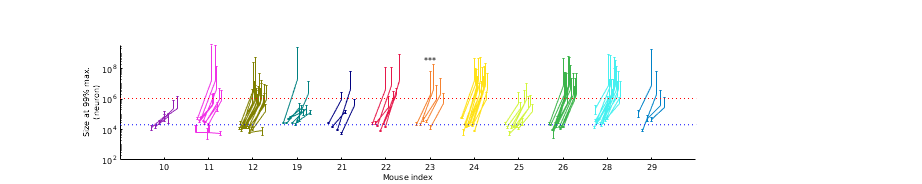

Value of 99N across mice: 2.871241e+04 +- 2.539278e+04 (95% conf)
Value of 99N (shuf) across mice: 2.896289e+06 +- 6.068929e+08 (95% conf)
Value of log(99N), postfunc: 1.150411e+04 - 4.203693e+04, mid: 2.199085e+04
Value of log(99N) (shuf), postfunc: 6.945264e-16 - 1.316307e+27, mid: 9.561432e+05


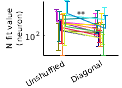

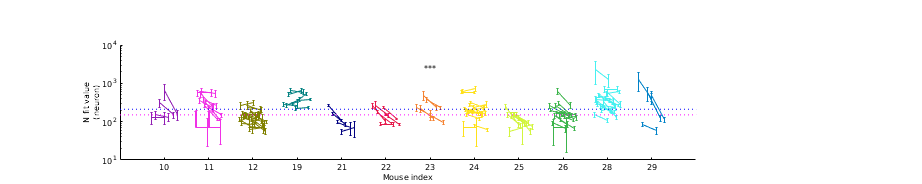

Value of N across mice: 2.900243e+02 +- 2.564928e+02 (95% conf)
Value of N (diag) across mice: 1.873559e+02 +- 1.180810e+02 (95% conf)
Value of log(N), postfunc: 1.162031e+02 - 4.246154e+02, mid: 2.221298e+02
Value of log(N) (diag), postfunc: 8.509172e+01 - 2.512409e+02, mid: 1.462140e+02


PanelGenerator.decoding_curves(true, true);